# Example 2: Analysis of an .stl file.

In this example, we will import and run various types of analysis on an stl file (provided with the toolbox).

## 2.1 Define the stl file and path for the file you wish to analyse

filepathname = "data/stls/3DBenchy.stl"; % Full name (and path) of the .stl file
mysurfaceMesh = surfaceMesh('stl',filepathname); % Create the surfaceMesh object from the .stl file

Calculate properties of the surfaceMesh object, define which method of curvature analysis you want to use.

"**none**" will produce the fastest result but have no curvature data - this is the default, and will be used for any other input.

"surfaceMesh" uses the surfaceMeshcurvature algorithm based on the paper:  Meyer, M., Desbrun, M., Schröder, P., & Barr, A. H. (2003). Discrete differential-geometry operators for triangulated 2-manifolds. Visualization and mathematics III (pp. 35-57). Springer Berlin Heidelberg. [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf)

"**patch**" uses the patch curvature function, written by D.Kroon University of Twente (August 2011) . This is based on a fitting a quadratic patch around each local vertex and it's neighbouring vertices. This is typically slower than the surfaceMeshcurvature algorithm.

curvatureMethod = "none"; % Define which method of curvature analysis ("none", "surfaceMesh", "patch")
mysurfaceMesh = mysurfaceMesh.calculateProperties(curvatureMethod);
faceProperties = fieldnames(mysurfaceMesh.Fproperty)

faceProperties = 7×1 cell array
    {'Nx'          }
    {'Ny'          }
    {'Nz'          }
    {'Finclination'}
    {'Fazimuth'    }
    {'Farea'       }
    {'Fvolume'     }


vertexProperties = fieldnames(mysurfaceMesh.Vproperty)

vertexProperties = 4×1 cell array
    {'inclination'}
    {'LPBFQuality'}
    {'Ra'         }
    {'Rz'         }


## 2.2 Preview the a colored surfaceMesh

Define the **property** you wish to preview. You may use any per-face or per-vertex property within **mysurfaceMesh**, the names of these properties may be found as the fields of **mysurfaceMesh.Fproperty** or **mysurfaceMesh.Vproperty **

You may specify to use "**fancy**" graphics, which will be used by default if nothing is specified.

You may also wish to pass in an **Axis**, which the surfaceMesh will be plotted on - by default a new axis will be created for the figure.

By default, the colorbar automatically scales to capture the 1st-99th percentile data.

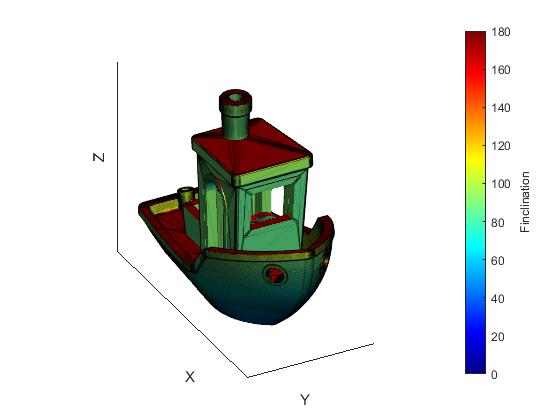

property = 'Finclination'; % property name must match the string before the space character
opt.fancy = 1; % boolean 1 or 0 to turn fancy graphics on or off.
figure; ax = gca; % gca uses the current axis object
mysurfaceMesh.plotMesh(property,ax,opt);

## 2.3 Convert to field data structure

Field based, or implicit data is an alternative way to define geometry. The TPMS designer package includes utilities to convert a surfaceMesh object to a **v3field** object which is a voxelised representation of the same geometry.

The user may define a voxel size, smaller numbers will result in higher computational cost, but better resolution.

If you wish to create properties, this can be done by modifying the **v3field.calculateProperties** function and saving the new properties under v3field.properties.

voxelSize = 1.0; %voxelsize in mm
myv3field=mysurfaceMesh.getField(voxelSize);
myv3field=myv3field.calculateProperties; % Call the calculate properties method to fill out property data
v3fieldnames = fieldnames(myv3field.property);

## 2.4 Preview and visualise field-based properties

Similarly to visualising property of a surfaceMesh, the user can visualise **v3field** properties.

You may specify a **sliceHeight** (as a percentage of the total object height) you with to preview the filed property at, this may be added/overlayed on previously made figures. Alternatively set **sliceHeight** = [] to utilise matlab's interactive orthosliceviewer.

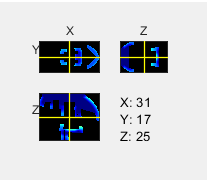

property = "manufacturability";
sliceHeight = []; 
h = myv3field.plotField(property,sliceHeight);

## 2.5 Further Data Analysis

The distribution of various proeprties can also give inishgts into the performance of a component.

For example, we can look at the probability density distribution of the manufacturability index. The index is defined as -1=empty space, and solid volume ranging from 0 to 1 - where 0 is likely to fail/have problems and 1 being produced without problems.

A design which is more suited to additive manufacturing will have a distribution with a small fraction close to 0 (or volume requiring support structures).

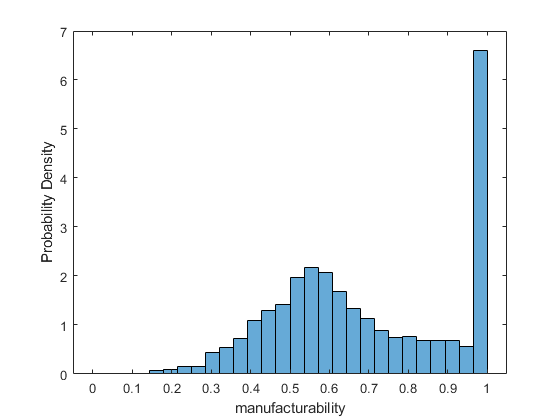

figure
temp = myv3field.property.manufacturability;
temp = temp(myv3field.property.surface==1);
histogram(temp,'BinLimits',[0 1],'Normalization',"pdf");
ylabel(gca,'Probability Density'); xlabel(gca,property);

## 2.6 Using metrics to compare different objects

As the structures investigated are highly complex and are often unwieldy to asses, TPMS Designer utilises a metrics-based approach. This allows a property of a complex design to be approximated with a simplified metric - these are used heavily in **example3_DOE** to compare various properties of TPMS-like structure in a large design of experiments. 

The **metrics** class includes a predefined set of normalised sums, means, maximums or defined percentiles value of various properties, as well as some mechanical metrics for use in comparing cellular structures.

Different metrics may require different properties to be calculated for the field or surface-mesh based representation of an object.

M = metrics;
fvMetrics = M.fvMetrics(mysurfaceMesh);
mechMetrics = M.mechanicalMetrics(myv3field);